% (C) Copyright 2020-2023 Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
clear all; %#ok
close all;
clc

# Static world (part 1)

## Introduction

Now that we understand the basics of the CoppeliaSim, we will start to interact with scene objects through the MATLAB interface. Before we start, however, let us add the namespace to our workspace. 

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

Please remember that MATLAB allows you to run this file section by section (Ctrl + Enter shortcut) if you want to follow this tutorial step by step.

Now, let us open the scene [static_world.ttt]. You should see something similar to the image below.

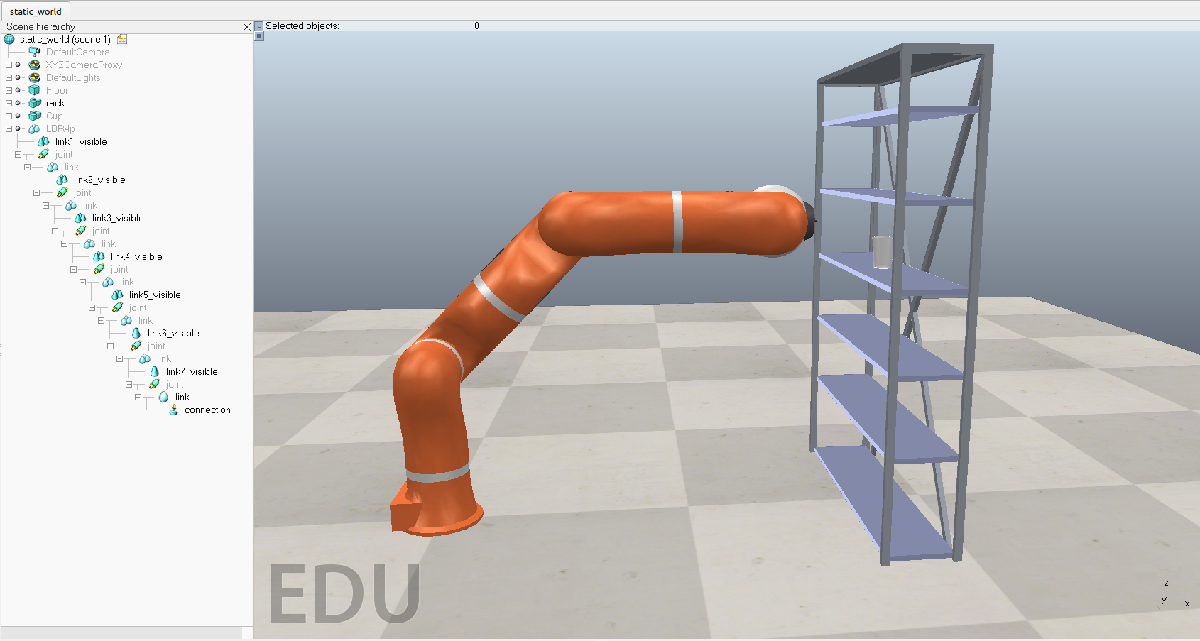

## Communicating with CoppeliaSim

Communication with CoppeliaSim is handled by the class 'DQ_VrepInterface'. We stablish communication by running

vi = DQ_VrepInterface();

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)
This version of DQ Robotics DQ_VrepInterface is compatible with VREP 3.5.0


vi.connect('127.0.0.1',19997);

Connected to the remote API server


From now until we break the communication, CoppeliaSim is ready to receive commands from MATLAB. Such as starting the simulation

vi.start_simulation();

You should see something similar to the image bellow in CoppeliaSim

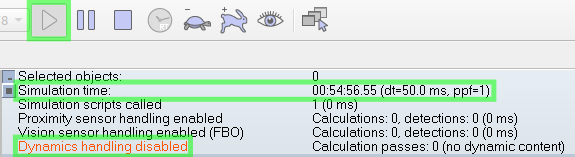

The grayed out 'Start/resume simulation' button, as well as the running clock, indicate that the simulation is currently running (even if the robot/objects aren't moving yet!). Additionally, the red warning is letting us know that [the dynamics is disabled](https://manual.coppeliarobotics.com/en/simulationPropertiesDialog.htm) (*it's a [static_world.ttt] after all (: *), which means CoppeliaSim is working as a visualization tool without using any of the available [physics engines](https://manual.coppeliarobotics.com/en/dynamicsModule.htm).

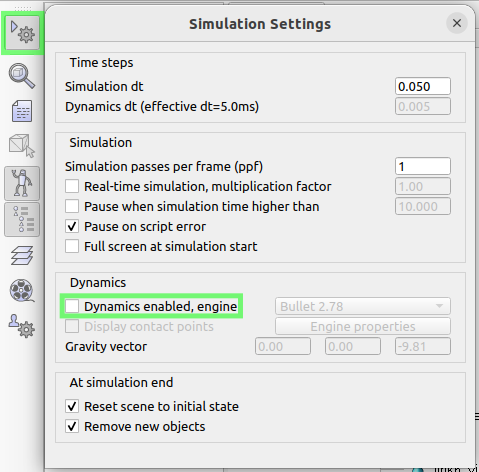

## Referring to an object in CoppeliaSim

Objects in CoppeliaSim have aliases, which you can see by selecting any of them. For instance, the cup's alias (name) is '/Cup'

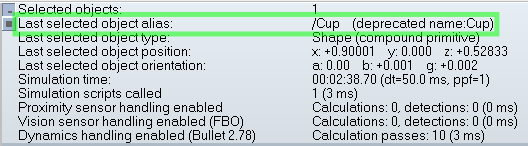

We can also refer to an object by its handle. For instance, we can get the cup's handle through its alias

vi.get_handle('/Cup')

ans = int32
18

Most methods in the class 'DQ_VrepInterface' require the object's alias to interact with it in CoppeliaSim, but the [underlying API methods](https://manual.coppeliarobotics.com/en/remoteApiFunctionsMatlab.htm) use the object's handle. The class 'DQ_VrepInterface' does this conversion from alias to handle automatically for you, but its important to keep this in mind in case you want to expand the list of currently supported methods in 'DQ_VrepInterface'. You can check this list in the class documentation or, more conveniently, use the 'help/doc' MATLAB functions (you can scroll through the box below and click on the methods if you want!).

help DQ_VrepInterface

  CLASS DQ_VrepInterface - Communicate with V-REP using dual quaternions.
 
  Installation:
    1) Enable V-REP's remote API on the Server Side:
    http://www.coppeliarobotics.com/helpFiles/en/remoteApiServerSide.htm
        - Port 19997 is enabled by default, please refer to the V-REP
        documentation if you need more ports.
    2) Enable V-REP's remote API on the Client Side:
    http://www.coppeliarobotics.com/helpFiles/en/remoteApiClientSide.htm
        You have to add two folders to your MATLAB path. For example, on
        64bit Windows:
            - YOUR_VREP_FOLDER\programming\remoteApiBindings\matlab\matlab
            - YOUR_VREP_FOLDER\programming\remoteApiBindings\lib\lib\Windows\64Bit
  For more information refer to the remote API documentation.
 
  Usage:
    If y

You can also check the documentation of specific methods if you are still unsure what their signature is. For example, the method 'get_object_translation', which we are going to use in the next section, requires only the object's alias.

help vi.get_object_translation

--- help for DQ_VrepInterface/get_object_translation ---

  This method gets the translation of an object in the CoppeliaSim scene.
 
  Usage:
      Recommended:
      t = get_object_translation(objectname) 
 
      Advanced:
      t = get_object_translation(objectname,reference_frame,opmode);  
 
           objectname:  The object name
           (optional) reference_frame:  Indicates the name of 
                        the relative reference frame in which you 
                        want the translation. If not specified, 
                        the absolute frame is used.
           (optional) opmode: The operation mode. If not specified, 
                        the opmode will be set automatically. 
                           
                         You can use the following modes:
                            OP_BLOCKING 
                            OP_STREAMING 
                            OP_ONESHOT 
                      

## Reading information from CoppeliaSim

'DQ_VrepInterface' allows us to get information about an object's location in the CoppeliaSim scene. For instance, we can get the cup's translation,

vi.get_object_translation('/Cup')

ans =          0.9i + 0.52833k

rotation,

vi.get_object_rotation('/Cup')

ans =          1

and pose.

vi.get_object_pose('/Cup')

ans =          (1) + E*(0.45i + 0.26417k)

Since we did not specify any reference frame, all the results above were given with respect to the inertial frame. However, in some situations we might be interested in the cup's pose with respect to a different reference frame. For instance, the end-effector of the KUKA LBR4+ robotic manipulator in the scene. We can get this information by defining '/LBR4p/connection' (the alias of the robot's end-effector) as our reference frame.

vi.get_object_pose('/Cup','/LBR4p/connection', vi.OP_BLOCKING)

ans =          (0.70711 + 6.1817e-08i - 0.70711j - 6.1817e-08k) + E*( - 3.8295e-05 + 0.075742i - 3.8291e-05j + 0.029776k)

## Sending commands to CoppeliaSim

Similarly to the use of 'Object/item shift' and 'Object/item rotate', we can move objects in a CoppeliaSim scene using the 'DQ_VrepInterface' class. For instance, we can move the cup to the top shelf

p = 0.900*i_ + 0.82833*k_;
vi.set_object_translation('/Cup', p);

and flip its orientation.

r = cos(pi/2) + i_*sin(pi/2);
vi.set_object_rotation('/Cup', r);

We can also take it out of the shelf.

p0 = 0.4*i_ + 0.4*k_;
x0 = 1 + (1/2)*E_*p0;
vi.set_object_pose('/Cup', x0);

Notice that since the dynamics are disabled the cup will not fall!

## Finishing communication with CoppeliaSim

After finishing the simulation, we can end the communication with CoppeliaSim.

vi.stop_simulation();
vi.disconnect_all();

# Homework

- Save the [static_world.ttt] scene as [static_world_part1_homework.ttt] and, in it, do 2-5.

- Read and store the rack's pose.

- Move the rack to position [0.900; 0.200; 0.400].

- Restore the rack to its initial pose.

- Bonus: lay the cup in the bottom shelf.